varTypes = {'int8','string','double','double'};
varNames = {'No','condition','PSE','slope'};
sz = [64 size(varTypes,2)];
H = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames);

% 定义实验者编号
for no = 69:69
    % 读取数据表格
    data = readtable("Metrics/eachCsv/" +  no + "_each.csv");

    % 定义condition名称数组
    cond_names = {'u1','f','u2'};

    % 合并condition和percent列，用于分组
    data.condition_percent = strcat(data.condition, '_', string(data.percent));

    % 分组计算异常值
    cond_groups = findgroups(data.condition_percent);
    data_no_outliers = table();
    outliers_count = table();
    for i = 1:length(cond_names)
        % 获取当前condition的数据
        cond_data = data(strcmp(data.condition, cond_names{i}),:);

        % 计算均值和标准差
        mean_RT = mean(cond_data.RT);
        sd_RT = std(cond_data.RT);
    
        % 计算异常值的范围
        outlier_lower = mean_RT - 3*sd_RT;
        outlier_upper = mean_RT + 3*sd_RT;

        % 去除异常值
        cond_data_no_outliers = cond_data(cond_data.RT >= outlier_lower & cond_data.RT <= outlier_upper,:);
        data_no_outliers = [data_no_outliers; cond_data_no_outliers];

        % 计算异常值数量
        outliers = cond_data(cond_data.RT < outlier_lower | cond_data.RT > outlier_upper,:);
        outlier_count = size(outliers,1);
        outlier_info = table(string(cond_names{i}), mean_RT, sd_RT, outlier_lower, outlier_upper, outlier_count, 'VariableNames', {'condition', 'mean_RT', 'sd_RT', 'outlier_lower', 'outlier_upper', 'outlier_count'});
        outliers_count = [outliers_count; outlier_info];
    end

    % 将去除异常值后的数据写入新表格
    filename_outliers = "Metrics/eachOutlier/mean_3sd/" +  no + "_outliers.csv";
    writetable(data_no_outliers, filename_outliers);
    
    % 输出异常值数量表格
    filename_outliers_count = "Metrics/eachOutlier/mean_3sd/"+  no + "_outliers_count.csv";
    writetable(outliers_count, filename_outliers_count);

end

varTypes = {'int8','string','double','double'};
varNames = {'No','condition','Threshold','slope'};
sz = [64 size(varTypes,2)];
H = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames);

T = 664×9 table
    No     sex     session    condition    percent    self_key    judge    RT     condition_percent
    __    _____    _______    _________    _______    ________    _____    ___    _________________

    69    {'f'}       1        {'u1'}         0        {'j'}        0      629        {'u1_0' }    
    69    {'f'}       1        {'u1'}         0        {'j'}        0      917        {'u1_0' }    
    69    {'f'}       1        {'u1'}         0        {'j'}        0      867        {'u1_0' }    
    69    {'f'}       1        {'u1'}         0        {'j'}        0      533        {'u1_0' }    
    69    {'f'}       1        {'u1'}         0        {'j'}        0      567        {'u1_0' }    
    69    {'f'}       1        {'u1'}        10        {'j'}        0      644        {'u1_10'}    
    69    {'f'}       1        {'u1'}        10        {'j'}        0      694        {'u1_10'}    
    69    {'f'}       1        {'u1'}        10        {'j'}        0      613     

width = 11.1450

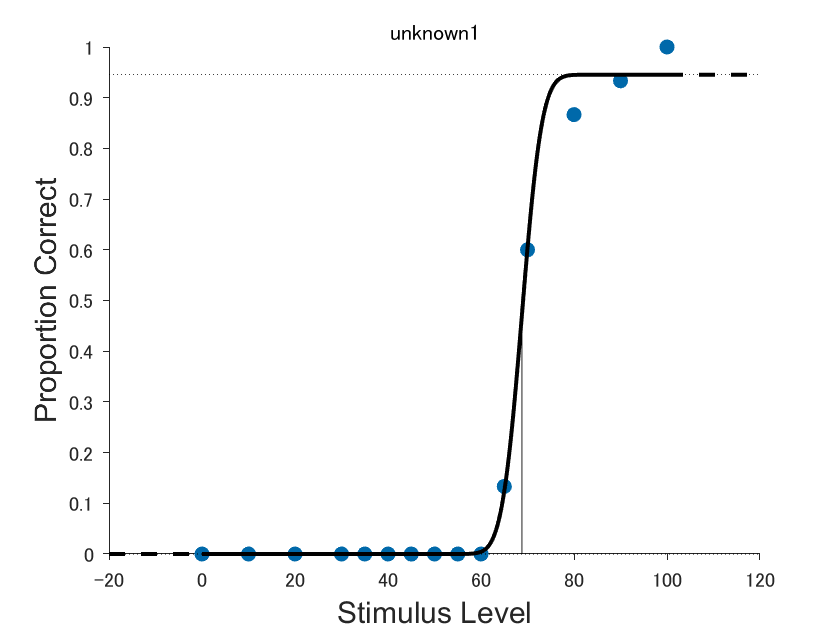

width = 30.7738

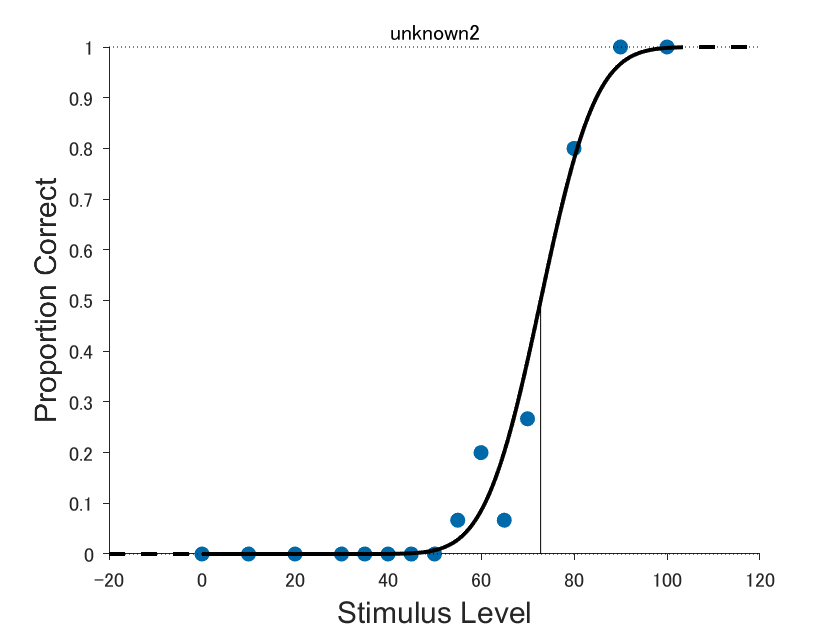

width = 17.9853

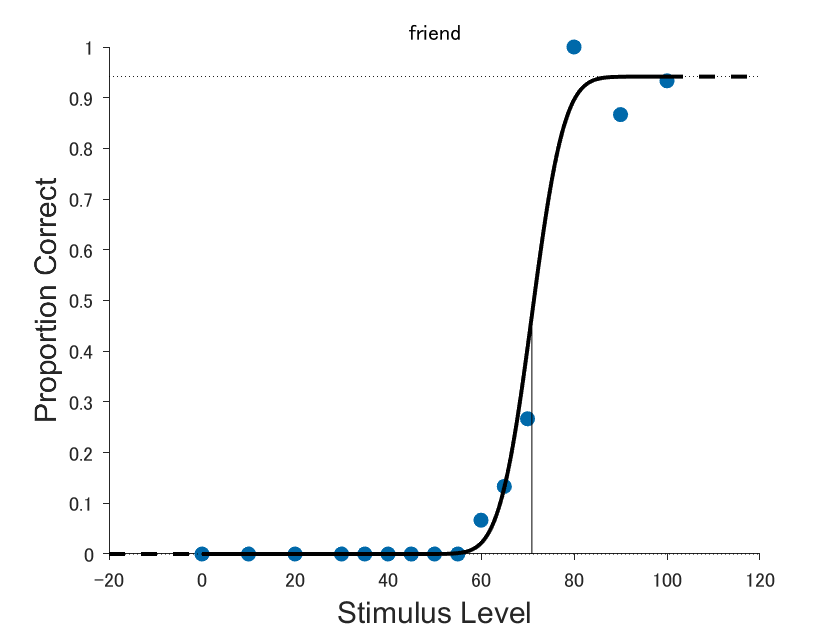

% psychofunction
% 初始化一个空表格用于汇总所有数据
all_H = table();

for j =69:69
    
no = j;
T = readtable("Metrics/eachOutlier/mean_3sd/" + num2str(no) + "_outliers.csv")

conditions = ["u1","u2","f"];
j_conditions = ["unknown1","unknown2","friend"];
keySet = {0,10,20,30,35,40,45,50,55,60,65,70,80,90,100};
valueSet = 1:15;
M = containers.Map(keySet,valueSet);
varTypes = {'int8','int8','int8'};
varNames = {'u1','u2','f'};
sz = [15 size(varTypes,2)];

C = table('Size',sz,'VariableTypes',varTypes,'VariableNames',varNames);
for i = 1:height(T)
    if T{i,"judge"} == 1
        C{M(T{i,"percent"}),T{i,"condition"}} = C{M(T{i,"percent"}),T{i,"condition"}} + 1;
    end
end
C;

Threshold = zeros(3,2);
for i = 1:3
    D = C{:,conditions(i)};
    data = zeros(15,3);
    data(:,1) = [0;10;20;30;35;40;45;50;55;60;65;70;80;90;100];
    data(:,2) = D;
    data(:,3) = 15;
    
    options             = struct;
    options.sigmoidName = 'norm';
    options.expType     = 'YesNo';
    options.confP = .80;
    result = psignifit(data,options);
    
    result.Fit;


        
    % 绘制心理曲线图
    figure
    plotPsych(result);
    title(j_conditions(i))

    %xlabel('Stimulus (self%)'); % 设置横坐标标签
    %ylabel('Threshold');        % 设置纵坐标标签
    resultSmall = rmfield(result,{'Posterior','weight'});
    
    % 计算斜率
    slope = getSlope(result, result.Fit(1));
    pse(i,:) = [result.Fit(1) slope];

    % 计算50%正确判断的阈值
    threshold = getThreshold(result, 0.5); 

    % 计算宽度
    width = result.Fit(2)
    
    H{(no-1)*3+i, "No"} = no;
    H{(no-1)*3+i,"condition"} = conditions(i);
    H{(no-1)*3+i,"Threshold"} = result.Fit(1);
    H{(no-1)*3+i,"slope"} = slope;
    H{(no-1)*3+i,"Width"} = width;    
    
    %resultSmall = rmfield(result,{'Posterior','weight'});
    
    %slope = getSlope(result, result.Fit(1));
    %Threshold(i,:) = [result.Fit(1) slope];
    %H{(no-1)*3+i, "No"} = no;
    %H{(no-1)*3+i,"condition"} = conditions(i);
    %H{(no-1)*3+i,"Threshold"} = result.Fit(1);
    %H{(no-1)*3+i,"slope"} = slope;
    %H{(no-1)*3+i,"Width"} = width;
    saveas(gcf, "Metrics/Threshold/mean_3sd/psychometric_function/" + num2str(no) +"_"+ conditions(i) + "_mean_3sd.png");
    writetable(H,"Metrics/Threshold/mean_3sd/each_mean_3sd/Threshold_" + num2str(no) + "_mean_3sd.csv");
end
%H
    % 将当前 no 的数据添加到汇总表格
    all_H = [all_H; H];
end

%writetable(all_H,"Metrics/Threshold/mean_3sd/Threshold_mean_3sd.csv")